# EE525 - Lab Project 1

Authors: Grant Gallagher, Alexander Goldstein, Yu-Shun Hsiao, Jacobis, Soriano Pelaez

Due: 10/8/2021

Objective:

## Part 1. Digital Communications

### Problem Statement

In a phase-shift keyed (**PSK**) digital communication system,  a binary digit (also termed a bit), which is either a “**0**” or a “**1**”, is communicated to a receiver by sending either$s_0 =\textrm{Acos}\left(2\pi F_0 t+\pi \;\right)$ to represent a “0” or $s_1 =\textrm{Acos}\left(2\pi F_0 t\;\right)$ to represent a “1”, where $A>0$. The receiver that is used to decode the transmission is shown in the figure below. The receiver that is used to decode the transmission is shown in the figure below. 

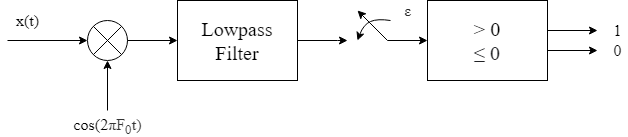

The input to the receiver is the noise corrupted signal or $x\left(t\right)=s_i \left(t\right)+w\left(t\right)$, where $w\left(t\right)$ represents the channel noise. It can be shown that in the absence of noise, the output of the lowpass filter is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2} & \mathrm{for}\;a\;"0"\\
\frac{A}{2} & \mathrm{for}\;a\;"1"
\end{array}\right.$$


The receiver decides a "1" was transmitted if $\zeta >0$ and a "0" if $\zeta \le 0$. To model the channel noise we assume that the actual value of $\zeta$ observed is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2}+W & \textrm{for}\;a\;"0"\\
\frac{A}{2}+W & \textrm{for}\;a\;"1"
\end{array}\right.$$


where $W$ is the Gaussian random variable, $W~N\left(0,1\right)$.

- Analytically determine the probability of error $P_e$, and plot it versus $A$.

- Use computer simulation to plot $P_e$ versus $A$ on the same graph as in 1 above.

- How should one choose $A$ so that the error probability does not exceed 0.01 (use the analytical result)? 

### 1 - Analytical Solution

clc;
clear;
clf;
syms A W x
P_0 = 0.5

P_0 = 0.5000

P_1 = 0.5;

Guass_Norm_pdf = 1/sqrt(2*pi) * exp((-(x)^2)/2);

Zeta_0_pdf = subs(Guass_Norm_pdf, x, (A/2 + W));
Zeta_1_pdf = subs(Guass_Norm_pdf, x, (A/2 - W));

P_e_given_0 = 1 - int(Zeta_0_pdf,W,-inf,0);
P_e_given_1 = int(Zeta_1_pdf,W,-inf,0);

P_e_analytical = P_e_given_0*P_0 + P_e_given_1*P_1;

### Computer Simulation

% n = 100; % Sample Size
% Astep = 20;
% 
% A = [-5:10/Astep:5];
% errors = zeros(length(A), 1);
% for k = 1:length(A)
%     dist = normrnd(A(k)/2, 1, [1 n]);
%     for m = 1:n
%         if dist(m) <= 0
%             errors(k) = errors(k) + 1;
%         end
%     end
% end
% 
% P_e_simulation_100 = errors/n;
% 
% n = 1000000
% A = [-5:10/Astep:5];
% errors = zeros(length(A), 1);
% for k = 1:length(A)
%     dist = normrnd(A(k)/2, 1, [1 n]);
%     for m = 1:n
%         if dist(m) <= 0
%             errors(k) = errors(k) + 1;
%         end
%     end
% end
% P_e_simulation_100k = errors/n;

### Plot

% figure
% hold on
% fplot(P_e_analytical, 'Color', [0 0 0])
% plot(A,P_e_simulation_100, '.', 'MarkerSize', 12, 'Color', [0.8750 0.2780 0.3840])
% plot(A,P_e_simulation_100k, '^', 'MarkerSize', 5, 'Color', [0 0.4470 0.7410], 'MarkerFaceColor', [0 0.4470 0.7410])
% hold off
% 
% legend('Analytical', 'Simulation, n=100', 'Simulation, n=100k')
% title("Cumulative Density Function of Flipped-Bit Error versus Magnitude of A")
% xlabel("Signal Magnitude, {\itA} [-]")
% ylabel("Probability of Error, {\itP_e} [-]")

## Part 2. COVID-19 Data Analysis

### Problem Statement

In this assignment, you will analyze the data to understand the Coronavirus pandemic, in particular, you will study the factors that might impact the mortality rate of COVID-19. You can find the dataset provided by *Our World in Data* [here](https://github.com/owid/covid-19-data/tree/master/public/data). It provides daily numbers on confirmed cases and deaths, testings, vaccinations, and other metrics for over 100 countries. For this study, consider the following data: *new_deaths_per_million* for the month of September 2021, *new_tests_per_thousand* for the same period, *people_vaccinated_per_hundred*, *aged_70_older*, *gdp_per_capita, cardiovasc_death_rate, diabetes_prevalence*. If a country misses any of the data, remove that country in this study.

- Plot the distribution of death rates for all countries. Compute the average death rates and the variance (Don’t use MATLAB built-in functions). What do these numbers tell us? Describe anything else you observe from the data.

- Study all other metrics. Plot their distributions, compute and interpret the average values and variances.

- Compute the correlation coefficients between the death rates and other metrics. What factor(s) affect the mortality rate the most? Plot the scatter diagram to support your argument. Describe anything else you observe from the data.

### Part 1

clc
clear
clf

raw_covid_data = readtable('owid-covid-data.csv');

countries = unique(raw_covid_data.location);

random_variable = {'avg_new_deaths_per_million', 'avg_new_tests_per_thousand', 'avg_people_vaccinated_per_hundred', ...
                   'avg_aged_70_older', 'avg_gdp_per_capita', 'avg_cardiovasc_death_rate', 'avg_diabetes_prevalence', ...
                   'var_new_deaths_per_million', 'var_new_tests_per_thousand', 'var_people_vaccinated_per_hundred', ...
                   'var_aged_70_older', 'var_gdp_per_capita', 'var_cardiovasc_death_rate', 'var_diabetes_prevalence'}

random_variable = 1×14 cell array
    {'avg_new_deaths_per_million'}    {'avg_new_tests_per_thousand'}    {'avg_people_vaccinated_per_hundred'}    {'avg_aged_70_older'}    {'avg_gdp_per_capita'}    {'avg_cardiovasc_death_rate'}    {'avg_diabetes_prevalence'}    {'var_new_deaths_per_million'}    {'var_new_tests_per_thousand'}    {'var_people_vaccinated_per_hundred'}    {'var_aged_70_older'}    {'var_gdp_per_capita'}    {'var_cardiovasc_death_rate'}    {'var_diabetes_prevalence'}



x = zeros(length(countries), length(random_variable))

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for k = 1:length(countries)
    new_deaths_per_million = raw_covid_data.new_deaths_per_million(string(raw_covid_data.location) == countries(k) & ...
                                                                   raw_covid_data.date >= '1-Sep-2021' & ...
                                                                   raw_covid_data.date <= '30-Sep-2021' & ...
                                                                   ~isnan(raw_covid_data.new_deaths_per_million));                     
    new_tests_per_thousand = raw_covid_data.new_tests_per_thousand(string(raw_covid_data.location) == countries(k) & ...
                                                                   raw_covid_data.date >= '1-Sep-2021' & ...
                                                                   raw_covid_data.date <= '30-Sep-2021' & ...
                                                                   ~isnan(raw_covid_data.new_tests_per_thousand));
    people_vaccinated_per_hundred = raw_covid_data.people_vaccinated_per_hundred(string(raw_covid_data.location) == countries(k) & ...
                                                                                 ~isnan(raw_covid_data.people_vaccinated_per_hundred));
    aged_70_older = raw_covid_data.aged_70_older(string(raw_covid_data.location) == countries(k) & ...
                                                                                 ~isnan(raw_covid_data.aged_70_older));
    gdp_per_capita = raw_covid_data.gdp_per_capita(string(raw_covid_data.location) == countries(k) & ...
                                                                                 ~isnan(raw_covid_data.gdp_per_capita));
    cardiovasc_death_rate = raw_covid_data.cardiovasc_death_rate(string(raw_covid_data.location) == countries(k) & ...
                                                                                 ~isnan(raw_covid_data.cardiovasc_death_rate));
    diabetes_prevalence = raw_covid_data.diabetes_prevalence(string(raw_covid_data.location) == countries(k) & ...
                                                                                 ~isnan(raw_covid_data.diabetes_prevalence));
    rv_vector = {new_deaths_per_million, new_tests_per_thousand, people_vaccinated_per_hundred, aged_70_older ...
                 gdp_per_capita, cardiovasc_death_rate, diabetes_prevalence};
             
    x(k,:) = [transpose(first_moment(rv_vector)), transpose(second_moment(rv_vector))];                           
end

t = array2table(x,'RowNames',countries,'VariableNames',random_variable)

t = 233×14 table
                           avg_new_deaths_per_million    avg_new_tests_per_thousand    avg_people_vaccinated_per_hundred    avg_aged_70_older    avg_gdp_per_capita    avg_cardiovasc_death_rate    avg_diabetes_prevalence    var_new_deaths_per_million    var_new_tests_per_thousand    var_people_vaccinated_per_hundred    var_aged_70_older    var_gdp_per_capita    var_cardiovasc_death_rate    var_diabetes_prevalence
                           __________________________    __________________________    _________________________________    _________________    __________________    _________________________    _______________________

## 1 - Death Rates in September

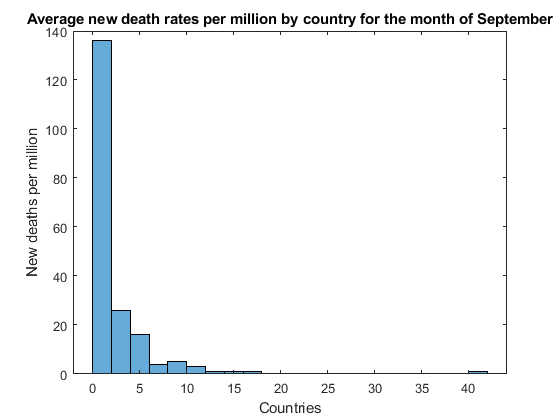

figure
histogram(t.avg_new_deaths_per_million)
title('Average new death rates per million by country for the month of September')
ylabel('New deaths per million')
xlabel('Countries')